# **上路+下路优化**

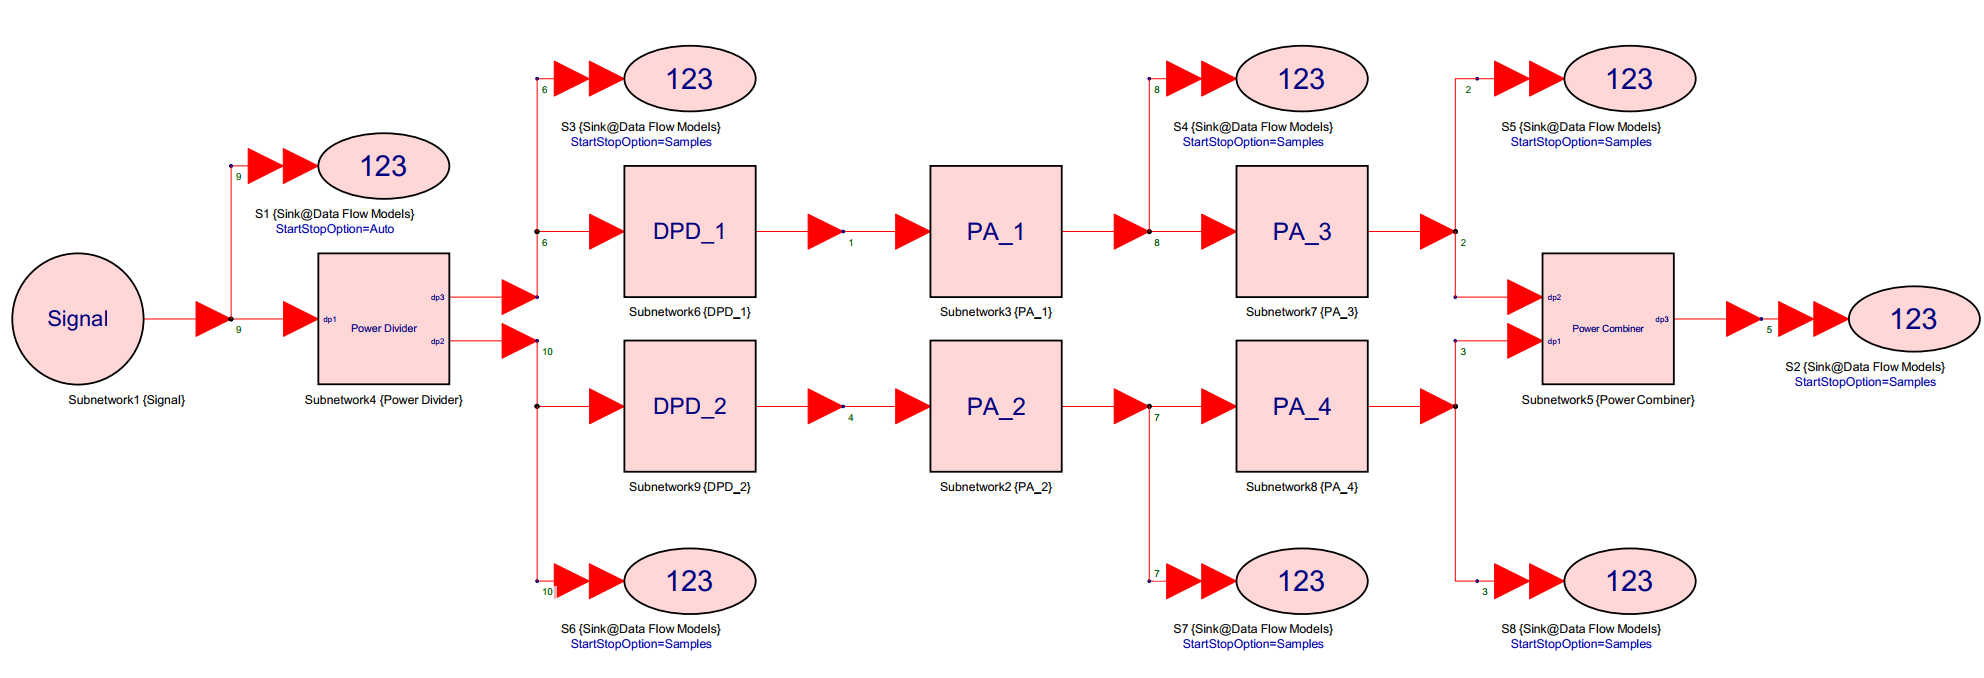

% 运行前请先将子文件夹添加到路径
clc; 

## -----------------------------Original System----------------------------

此模型是完全固定的！

clear;
% 读取文件并处理数据
[Data_matrix,dim]=ReadFile_Original();
Sys_input = Data_matrix(:,1) + 1i * Data_matrix(:,2); 
Original_output = Data_matrix(:,end-1) + 1i * Data_matrix(:,end); 
% 模型仿真
[U1,D1]=Power_Divider(Sys_input);
U2=PA_1(U1);
U3=PA_3(U2);
D2=PA_2(D1);
D3=PA_4(D2);
Original_output_sim=Power_Combiner(U3,D3);
% 性能评估
err=abs(Original_output_sim-Original_output) %模型本身的误差

err = 1.0e-13 *

    0.0037
    0.0030
    0.0057
    0.0049
    0.0051
    0.0050
    0.0098
    0.0063
    0.0109
    0.0111


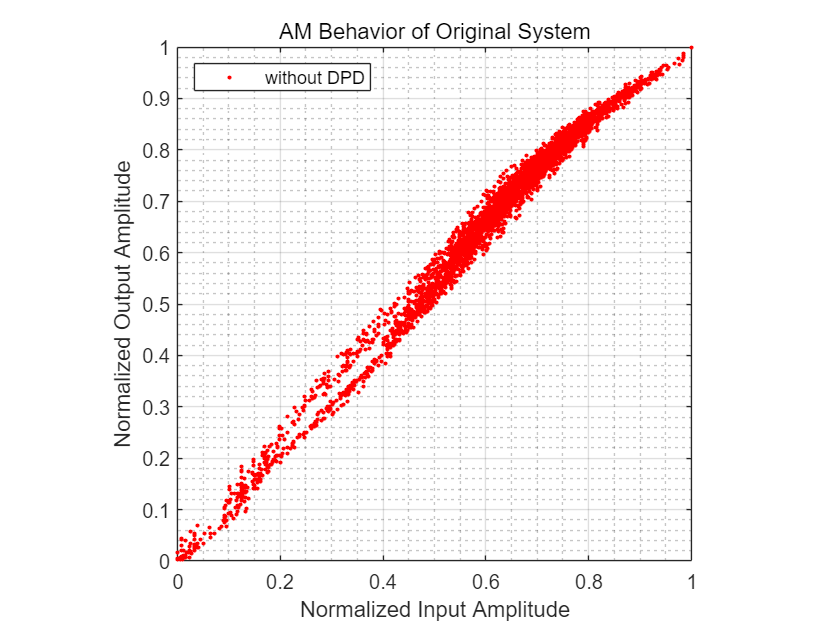

Plot_AM(Sys_input,Original_output_sim,'AM Behavior of Original System','without DPD');

nmse_sim= NMSE_dB(Sys_input,Original_output_sim);
nmse_act = NMSE_dB(Sys_input,Original_output);
fprintf('不使用DPD，系统的NMSE仿真结果为 %f dB\n', nmse_sim);

不使用DPD，系统的NMSE仿真结果为 -16.688242 dB


fprintf('不使用DPD，系统的NMSE实测结果为 %f dB\n', nmse_act);

不使用DPD，系统的NMSE实测结果为 -16.688242 dB


## -----------------------------Model A2 System----------------------------

## 读取数据

clear;
% 读取文件并处理数据
[Data_matrix,dim]=ReadFile_Original();
% 根据需要选取原始数据
Sys_x_i=Data_matrix(:,1);Sys_x_q=Data_matrix(:,2);
Sys_y_i=Data_matrix(:,15);Sys_y_q=Data_matrix(:,16);
Sys_input = Sys_x_i + 1i * Sys_x_q;
Sys_output = Sys_y_i + 1i * Sys_y_q;
PA1_x_i=Data_matrix(:,3);PA1_x_q=Data_matrix(:,4);
PA3_y_i=Data_matrix(:,11);PA3_y_q=Data_matrix(:,12);
PA1_input = PA1_x_i + 1i * PA1_x_q;
PA3_output = PA3_y_i + 1i * PA3_y_q;
PA2_x_i=Data_matrix(:,5);PA2_x_q=Data_matrix(:,6);
PA4_y_i=Data_matrix(:,13);PA4_y_q=Data_matrix(:,14);
PA2_input = PA2_x_i + 1i * PA2_x_q;
PA4_output = PA4_y_i + 1i * PA4_y_q;

## 训练上路(训练一次即可)

｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　轮　　｜　　迭代　　｜　　　　经过的时间　　　　　｜　　小批量　ＲＭＳＥ　　｜　　验证　ＲＭＳＥ　　｜　　小批量损失　　｜　　验证损失　　｜　　基础学习率　　｜
｜　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　｜　　　　　　　　　　　｜　　　　　　　　　｜　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　１　｜　　　　１　｜　　　　　００：００：０１　｜　　　　　　　０．６５　｜　　　　　　０．５９　｜　　０．２１３３　｜　０．１７１４　｜　　０．００３０　｜
｜　　８０　｜　　　８０　｜　　　　　００：００：０２　｜　　　　　　　０．０６　｜　　　　　　０．０６　｜　　０．００１７　｜　０．００１６　｜　　０．００３０　｜
｜　１６０　｜　　１６０　｜　　　　　００：００：０４　｜　　　　　　　０．０４　｜　　　　　　０．０４　｜　　０．０００９　｜　０．００１０　｜　　０．００３０　｜
｜　２４０　｜　　２４０　｜　　　　　００：００：０６　｜　　　　　　　０．０４　｜　　　　　　０．０４　｜　　０．０００８　｜　０．００１０　｜　　０．００３０　｜
｜　３２０　｜　　３２０　｜　　　　　００：００：１０　｜　　　　　　　０．０４　｜　　　　　　０．０３　｜　　０．０００９　｜　０．０００５　｜　　０．００３０　｜
｜　４００　｜　　４００　｜　　　　　００：００：１３　｜　　　　　　　０．０３　｜　　　　　　０．０４　｜　　０．０００５　｜　０．０００７　｜　　０．００３０　｜
｜　４８０　｜　　４８０　｜　　　　　００：００：１６　｜　　　　　　　０．０３　｜　　　　　　０．０３　｜　　０．０００４　｜　０．０００６　｜　　０．００３０　｜
｜　５６０　｜　　５６０　｜　　　　　００：００：２０　｜　　　　　　　０．０３　｜　　　　　　０．０３　｜　　０．０００３　｜　０．０００４　｜　　０

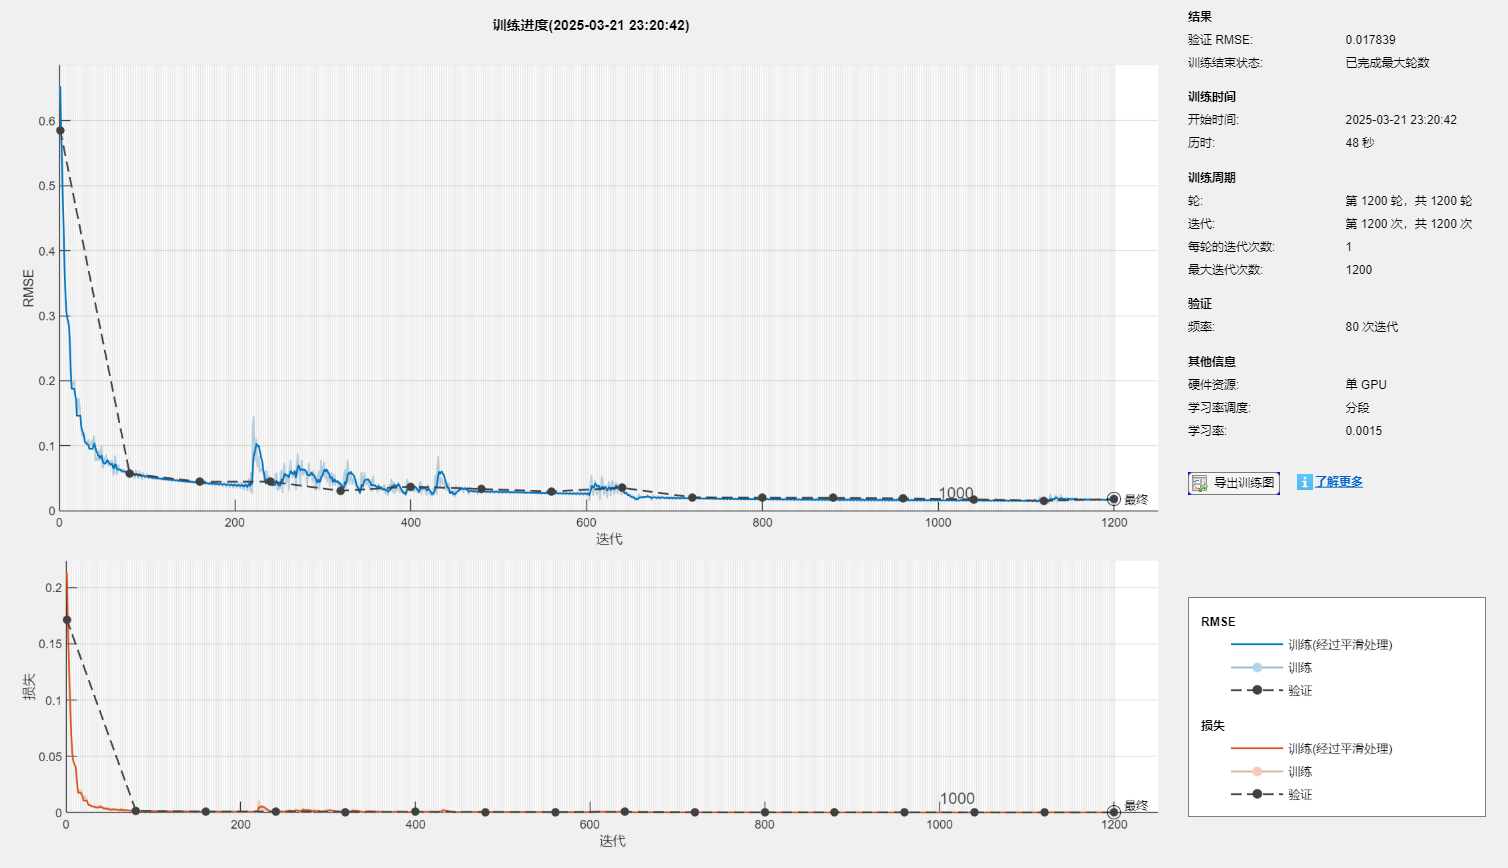

% %%%%%%%%%%%%%%%%%%%%%%%%%% 1：FNN %%%%%%%%%%%%%%%%%%%%%%%%%%
% FNN = FNN_train(PA1_x_i,PA1_x_q,PA3_y_i,PA3_y_q,7);
% save('Algorithm_B\Alg_Upper.mat', 'FNN','-append');

%%%%%%%%%%%%%%%%%%%%%%%%%% 10：Simple FCN %%%%%%%%%%%%%%%%%%%%%%%%%%
Simple_FCN=simpleFCN_train(PA1_x_i,PA1_x_q,PA3_y_i,PA3_y_q,7);

save('Algorithm_B\Alg_Upper.mat', 'Simple_FCN','-append');

## 训练下路(训练一次即可)

｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　轮　　｜　　迭代　　｜　　　　经过的时间　　　　　｜　　小批量　ＲＭＳＥ　　｜　　验证　ＲＭＳＥ　　｜　　小批量损失　　｜　　验证损失　　｜　　基础学习率　　｜
｜　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　｜　　　　　　　　　　　｜　　　　　　　　　｜　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　１　｜　　　　１　｜　　　　　００：００：０１　｜　　　　　　　０．６６　｜　　　　　　０．６１　｜　　０．２１７６　｜　０．１８４６　｜　　０．００３０　｜
｜　　８０　｜　　　８０　｜　　　　　００：００：０４　｜　　　　　　　０．０６　｜　　　　　　０．０６　｜　　０．００１８　｜　０．００１８　｜　　０．００３０　｜
｜　１６０　｜　　１６０　｜　　　　　００：００：０６　｜　　　　　　　０．０５　｜　　　　　　０．０４　｜　　０．００１３　｜　０．０００９　｜　　０．００３０　｜
｜　２４０　｜　　２４０　｜　　　　　００：００：１０　｜　　　　　　　０．０４　｜　　　　　　０．０４　｜　　０．０００９　｜　０．０００９　｜　　０．００３０　｜
｜　３２０　｜　　３２０　｜　　　　　００：００：１３　｜　　　　　　　０．０４　｜　　　　　　０．０４　｜　　０．０００９　｜　０．０００６　｜　　０．００３０　｜
｜　４００　｜　　４００　｜　　　　　００：００：１７　｜　　　　　　　０．０３　｜　　　　　　０．０３　｜　　０．０００６　｜　０．０００５　｜　　０．００３０　｜
｜　４８０　｜　　４８０　｜　　　　　００：００：２０　｜　　　　　　　０．０３　｜　　　　　　０．０３　｜　　０．０００５　｜　０．０００４　｜　　０．００３０　｜
｜　５６０　｜　　５６０　｜　　　　　００：００：２４　｜　　　　　　　０．０３　｜　　　　　　０．０３　｜　　０．０００５　｜　０．０００６　｜　　０

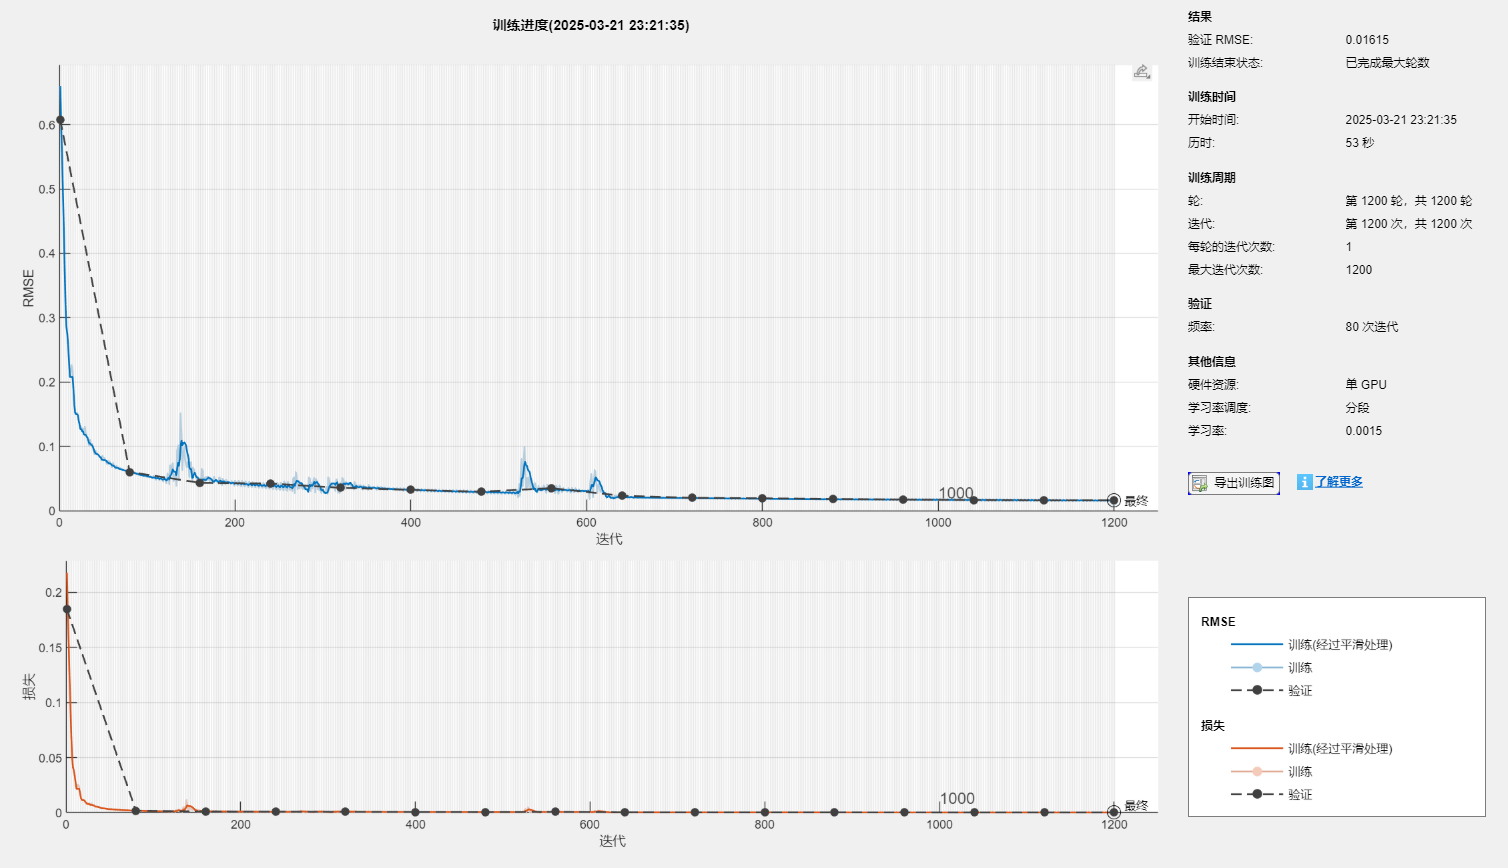

% %%%%%%%%%%%%%%%%%%%%%%%%%% 1：FNN %%%%%%%%%%%%%%%%%%%%%%%%%%
% FNN = FNN_train(PA2_x_i,PA2_x_q,PA4_y_i,PA4_y_q,7);
% save('Algorithm_B\Alg_Lower.mat', 'FNN','-append');

%%%%%%%%%%%%%%%%%%%%%%%%%% 10：Simple FCN %%%%%%%%%%%%%%%%%%%%%%%%%%
Simple_FCN=simpleFCN_train(PA2_x_i,PA2_x_q,PA4_y_i,PA4_y_q,7);

save('Algorithm_B\Alg_Lower.mat', 'Simple_FCN','-append');

## Model Test

% 参数需要保持一致
M = 7;
% 系统模拟
[S_U1,S_D1]=Power_Divider(Sys_input);
S_U1_DPD= DPD(S_U1,M,10,'Algorithm_B\Alg_Upper.mat');% input,记忆深度,不同算法,不同位置
S_U2    = PA_1(S_U1_DPD);
S_U3    = PA_3(S_U2);
S_D1_DPD= DPD(S_D1,M,10,'Algorithm_B\Alg_Lower.mat');% input,记忆深度,不同算法,不同位置
S_D2    = PA_2(S_D1_DPD);
S_D3    = PA_4(S_D2);
Sys_output_sim=Power_Combiner(S_U3,S_D3);

% 性能评估
nmse_DPD=Get_nmse_DPD(Sys_output_sim,Sys_output);
fprintf('单级DPD的相对NMSE为 %f dB\n', nmse_DPD);

单级DPD的相对NMSE为 -17.486959 dB


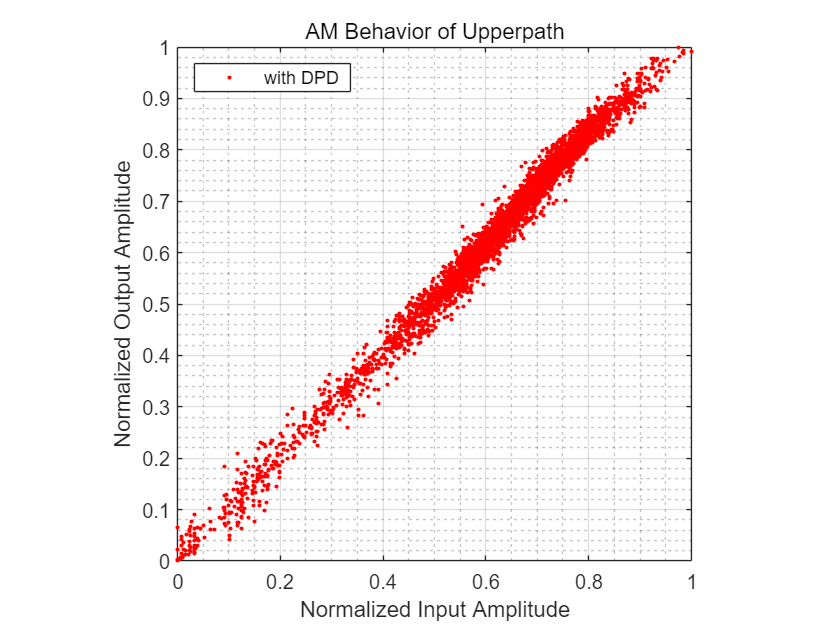

Plot_AM(S_U1,S_U3,'AM Behavior of Upperpath','with DPD');

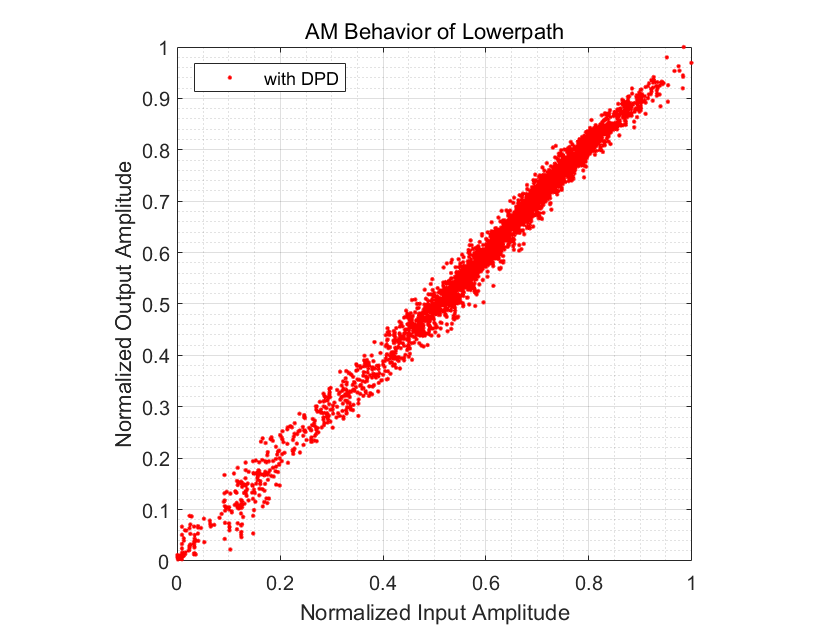

Plot_AM(S_D1,S_D3,'AM Behavior of Lowerpath','with DPD');

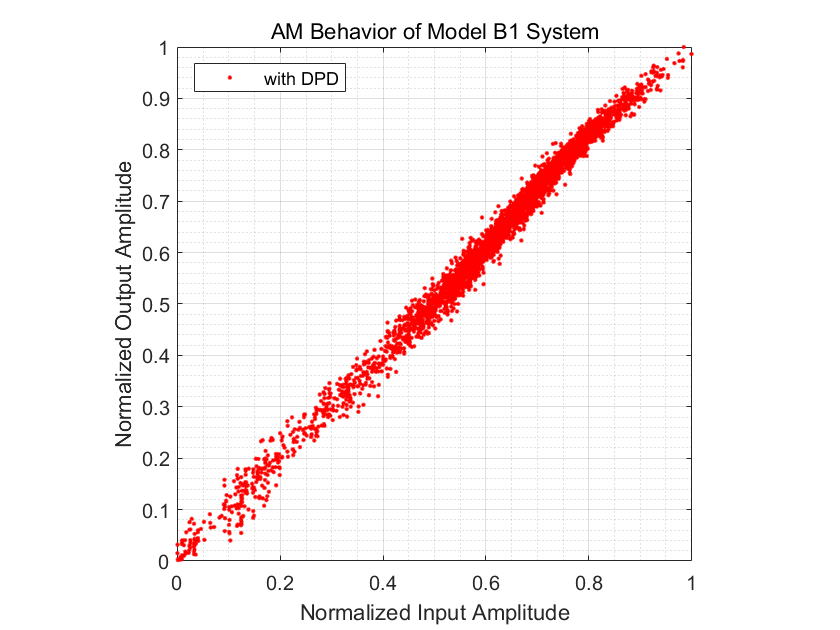

Plot_AM(Sys_input,Sys_output_sim,'AM Behavior of Model B1 System','with DPD');

nmse_sim= NMSE_dB(Sys_input,Sys_output_sim);
fprintf('使用Model A3，系统的NMSE仿真结果为 %f dB\n', nmse_sim);

使用Model A3，系统的NMSE仿真结果为 -25.391193 dB
